%Common Tern
TbyW_d = 0.8433803459737902;
WbyS_d = 27.2431; %N/m2
R = 0.828/2;
b = 0.828/2;
AR = 12.2/2

AR = 6.1000

U = 15 %m/s

U = 15

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tau = 0.5

tau = 0.5000

%f = 4.07895 %flapping frequency
%T = 1/f
%phi = 1.0935*2 %flapping amplitude, in m (not in angles!)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%CD_0 = 0.02
%C_L = 0.437
%C_D = 0.344

W1 = 0.118 %kg, multiply by 9.81! (multiplication done in line for calculation of P)

W1 = 0.1180

W = 0;
g = 9.81

g = 9.8100

r2_cap = 0.4518

r2_cap = 0.4518

rcp_cap = 0.25

rcp_cap = 0.2500

i = 0

i = 0

C_L = 1.5

C_L = 1.5000


rho = 1.1033 %si sea level

rho = 1.1033

q = (1/2)*rho*U^2 %at sl

q = 124.1212

S = 0.056 %m2

S = 0.0560

e = 0.8 %assumed value for oswalds number

e = 0.8000

k1 = 1/(pi*AR*e)

k1 = 0.0652

k2 = 0

k2 = 0

n = 1

n = 1

beta = 1

beta = 1

cd0 = 0.03 % its 3 percent for most of the Mavs

cd0 = 0.0300

D = q*S*((k1*((n*beta*W1)/(q*S)))+(k2*((n*beta)/(q*S)))+cd0)

D = 0.2162

C_D = k1*C_L^2 + k2*C_L + cd0

C_D = 0.1768

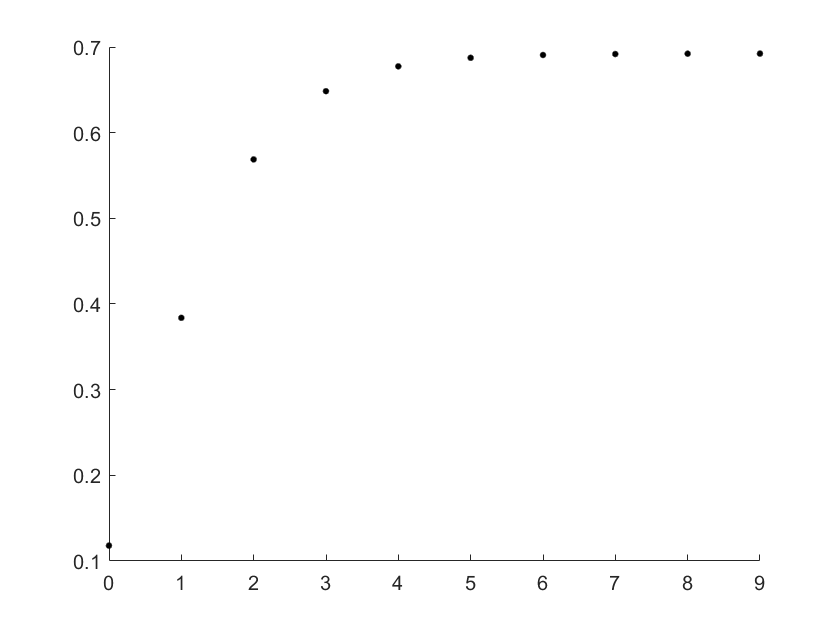

i = 1

P = 9.7665

W = 0.3839

i = 2

P = 31.7723

W = 0.5688

i = 3

P = 47.0781

W = 0.6485

i = 4

P = 53.6713

W = 0.6774

i = 5

P = 56.0682

W = 0.6874

i = 6

P = 56.8908

W = 0.6907

i = 7

P = 57.1676

W = 0.6918

i = 8

P = 57.2602

W = 0.6922

i = 9

P = 57.2911

W = 0.6923

i = 10

P = 57.3014

W = 0.6924

hold on

while 1==1
    plot(i,W1, 'k.', 'MarkerSize',10)
    i = i+1
    P = 8.437*W1*9.81
    W = (((P*C_L^3*r2_cap^2*rho*R^2)/(2*C_D^2*rcp_cap^2*AR))^(1/3))/9.81 %mass in kg
    if abs(W-W1)<=0.0001
        break
    else
        W1 = W;
    end
end

P = 8.437*W*9.81

P = 57.3048

%f
%phi*180/pi/2
%Weight Fractions
wf_str = 0.1337*(W*1000)^(0.2667)

wf_str = 0.7650

wf_bat = 0.5572*(W*1000)^(-0.244)

wf_bat = 0.1130

wf_el = 1.0816*(W*1000)^(-0.277)

wf_el = 0.1767